## Exercise 1:

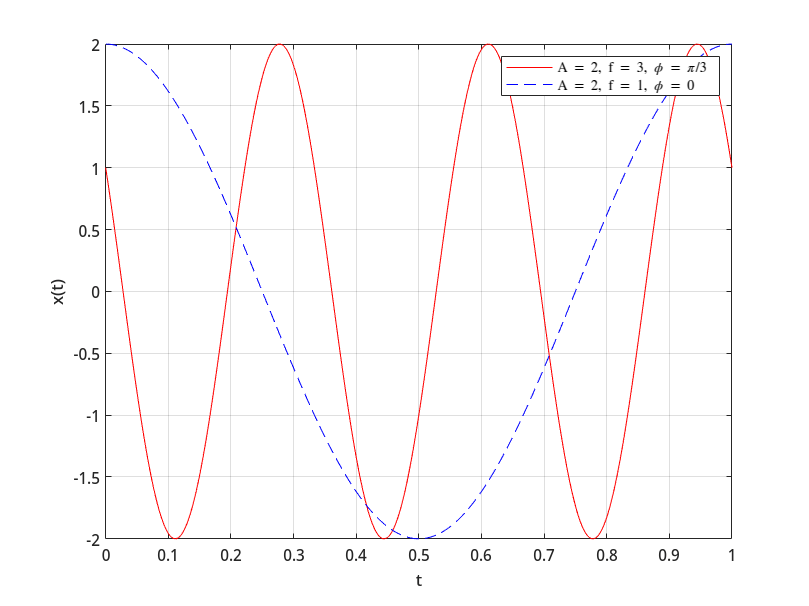

sinusoid = @(a, f, p) @(t) a .* cos(2*pi*f*t + p);

amp1   = 2;
freq1  = 3;
phase1 = pi/3;
f1 = sinusoid(amp1, freq1, phase1);

amp2   = 2;
freq2  = 1;
phase2 = 0;
f2 = sinusoid(amp2, freq2, phase2);

nperiods = 3;
tmin = 0;
tmax = nperiods / freq1;
res  = 1000;
inc  = (tmax - tmin) / res;

ts  = tmin : inc : tmax;
ss1 = f1(ts);
ss2 = f2(ts);

plot(ts, ss1, 'r-');
hold on;
plot(ts, ss2, 'b--');
hold off;
xlabel('t');
ylabel('x(t)');
legend('A = 2, f = 3, \phi = \pi/3', 'A = 2, f = 1, \phi = 0');
grid on;

## Exercise 2:

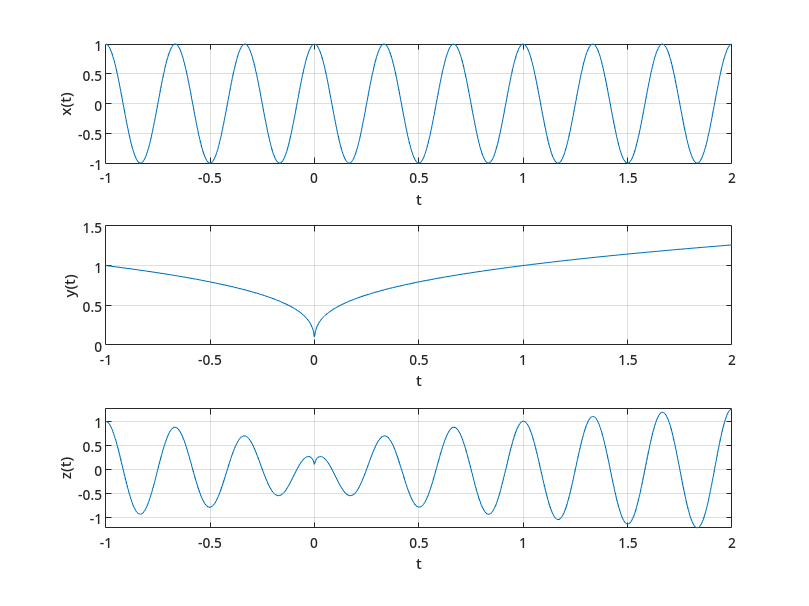

tmin = -1;
tmax = 2;
inc  = (tmax - tmin) / res;

x = @(t) cos(6*pi*t);
y = @(t) nthroot(abs(t), 3);
z = @(t) x(t).*y(t);

ts  = tmin : inc : tmax;
xs = x(ts);
ys = y(ts);
zs = z(ts);

subplot(3, 1, 1);
plot(ts, xs);
xlabel('t');
ylabel('x(t)');
grid on;

subplot(3, 1, 2);
plot(ts, ys);
xlabel('t');
ylabel('y(t)');
grid on;

subplot(3, 1, 3);
plot(ts, zs);
xlabel('t');
ylabel('z(t)');
grid on;

## Exercise 3:

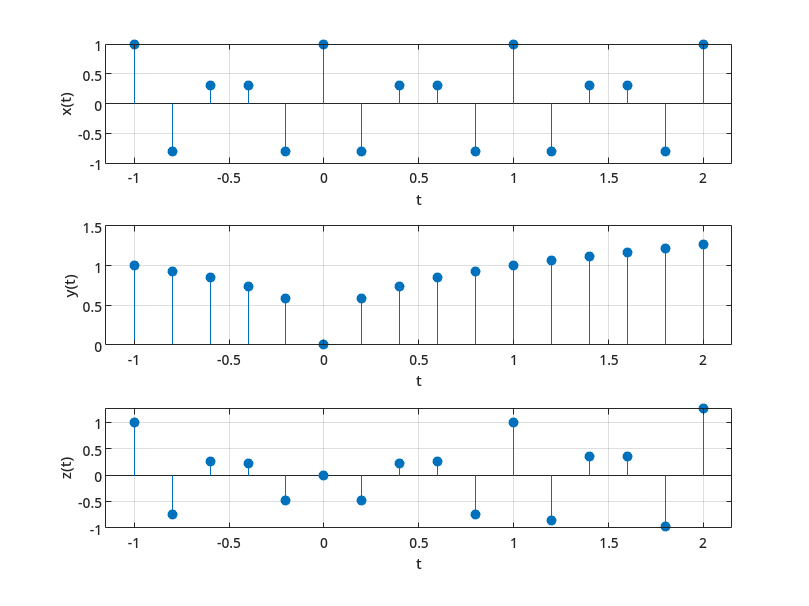

stime = 1/5;

ts = tmin : stime : tmax;
xs = x(ts);
ys = y(ts);
zs = z(ts);

figure;
subplot(3, 1, 1);
stem(ts, xs, 'filled');
xlabel('t');
ylabel('x(t)');
grid on;

subplot(3, 1, 2);
stem(ts, ys, 'filled');
xlabel('t');
ylabel('y(t)');
grid on;

subplot(3, 1, 3);
stem(ts, zs, 'filled');
xlabel('t');
ylabel('z(t)');
grid on;

## Exercise 5:

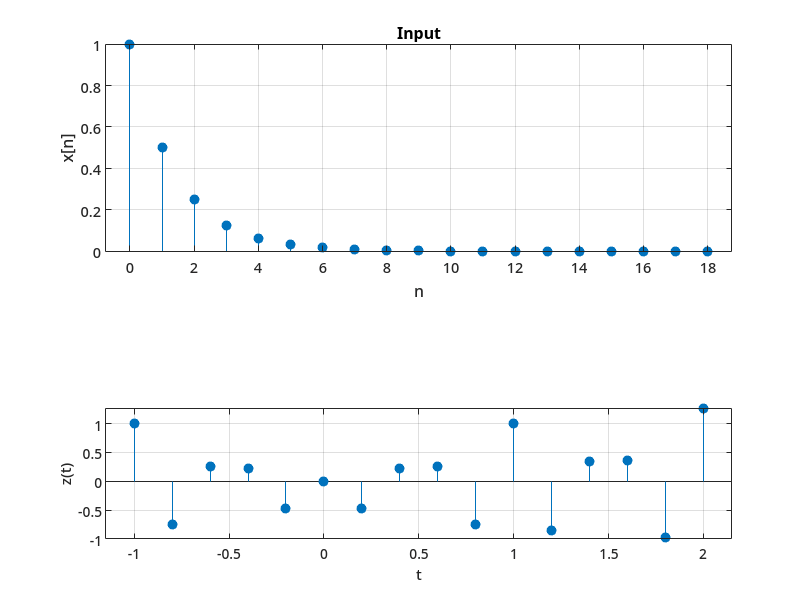

% x is defined for 0 ≤ n ≤ 10, System 1 operates on 8 inputs.
ns = 0 : 18;

function y = x1(n)
    if 0 <= n & n <= 10
        y = (1/2).^n;
    else
        y = 0;
    end
end

function h = h1(n)
    if 0 <= n & n <= 7
        h = 1/8;
    else
        h = 0;
    end
end

xs = arrayfun(@x1, ns);
hs = arrayfun(@h1, ns);
ys = conv(xs, hs);
% Trim trailing zeroes.
ys = ys(1 : length(ns));

subplot(2, 1, 1);
stem(ns, xs, 'filled');
xlabel('n');
ylabel('x[n]');
title('Input');
grid on;

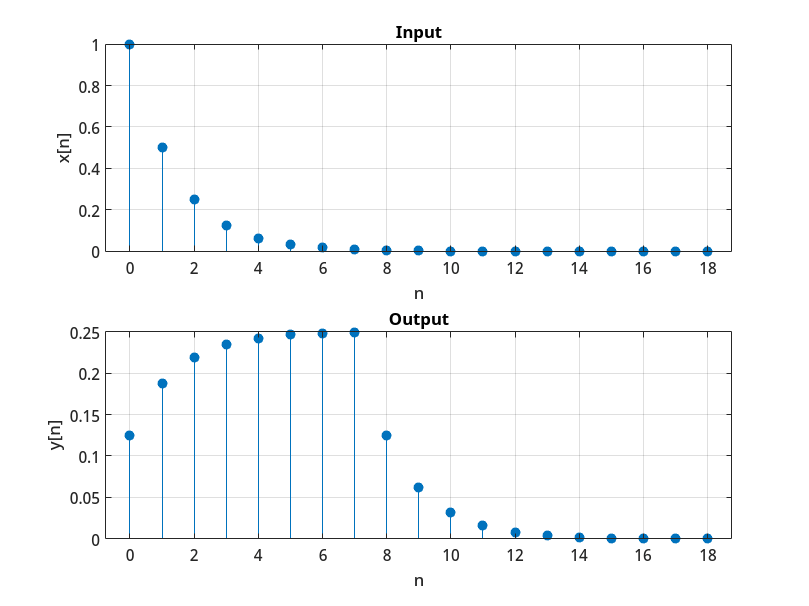


subplot(2, 1, 2);
stem(ns, ys, 'filled');
xlabel('n');
ylabel('y[n]');
title('Output');
grid on;

## Exercise 6:

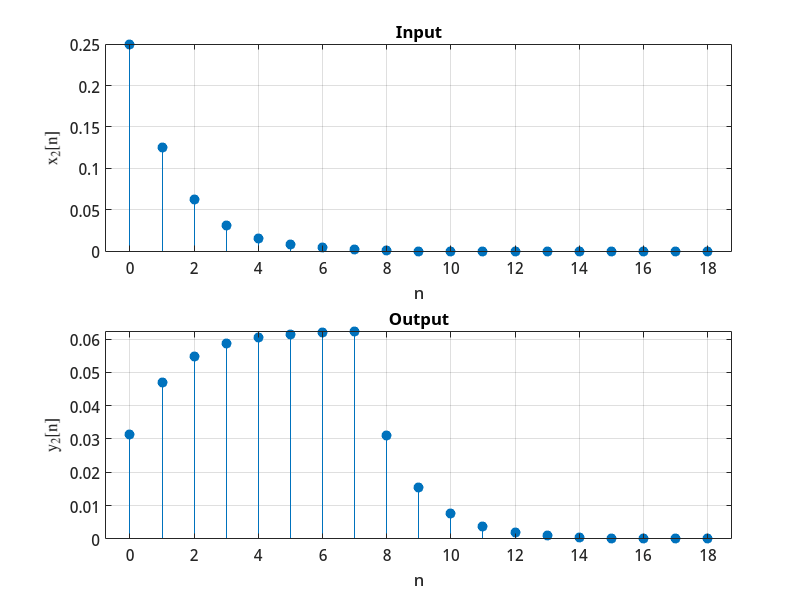

x2 = @(n) x1(n + 2);

xs = arrayfun(x2, ns);
ys = conv(xs, hs);
ys = ys(1 : length(ns));

figure;
subplot(2, 1, 1);
stem(ns, xs, 'filled');
xlabel('n');
ylabel('x_2[n]');
title('Input');
grid on;

subplot(2, 1, 2);
stem(ns, ys, 'filled');
xlabel('n');
ylabel('y_2[n]');
title('Output');
grid on;

## Exercise 7:

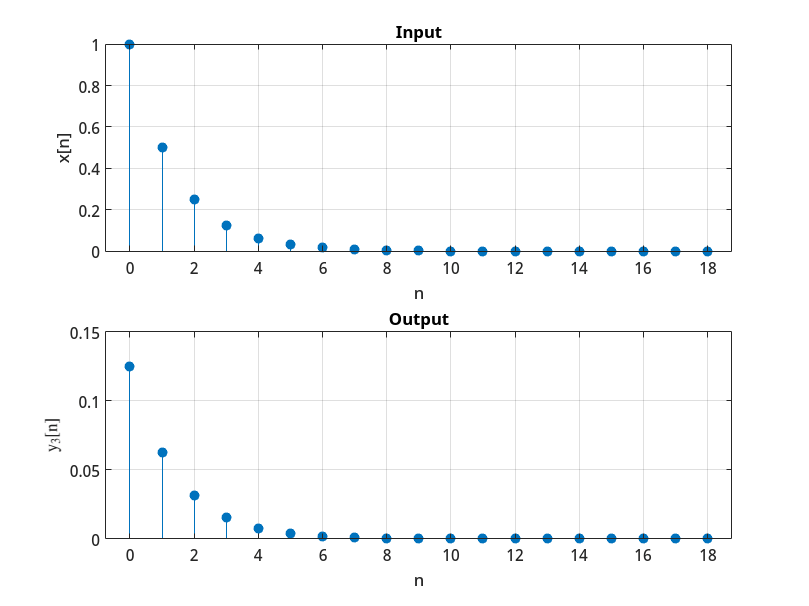

h2 = @(n) h1(-n);

xs = arrayfun(@x1, ns);
hs = arrayfun(h2, ns);
ys = conv(xs, hs);
ys = ys(1 : length(ns));

figure;
subplot(2, 1, 1);
stem(ns, xs, 'filled');
xlabel('n');
ylabel('x[n]');
title('Input');
grid on;

subplot(2, 1, 2);
stem(ns, ys, 'filled');
xlabel('n');
ylabel('y_3[n]');
title('Output');
grid on;

## Exercise 8:

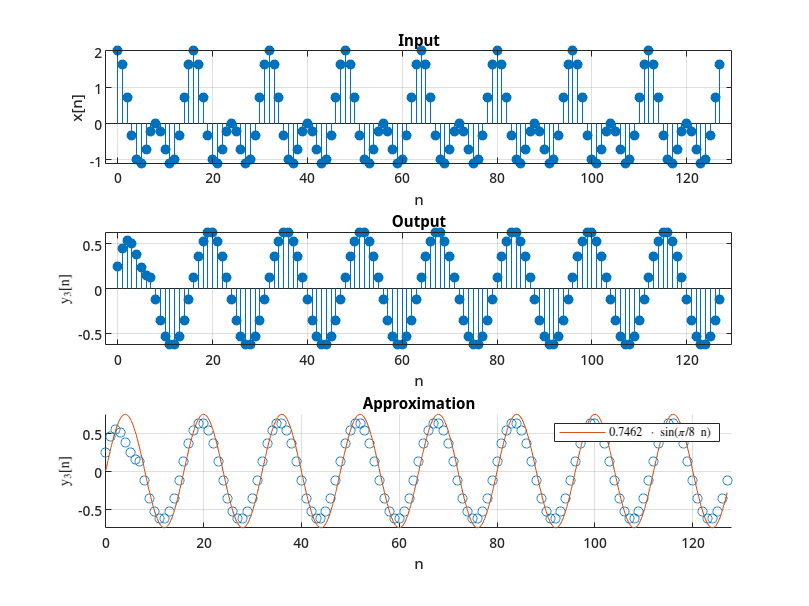

ns = 0 : 127;

function y = x4(n)
    if 0 <= n & n <= 127
        y = cos(pi/8*n) + cos(pi/4*n);
    else
        y = 0;
    end
end

xs = arrayfun(@x4, ns);
hs = arrayfun(@h1, ns);
ys = conv(xs, hs);
ys = ys(1 : length(ns));

nfine = 0 : 0.1 : 127;
% Found analytically, approximately 0.7462.
amp = (sqrt(2-sqrt(2)) + 2*sqrt(2+sqrt(2+sqrt(2)))) / (2*pi);
approx = @(t) 0.7462*sin(pi/8*t);
yfine = approx(nfine);

figure;
subplot(3, 1, 1);
stem(ns, xs, 'filled');
xlabel('n');
ylabel('x[n]');
title('Input');
grid on;

subplot(3, 1, 2);
stem(ns, ys, 'filled');
xlabel('n');
ylabel('y_3[n]');
title('Output');
grid on;

subplot(3, 1, 3);
scatter(ns, ys);
hold on;
plot(nfine, yfine);
hold off;
xlim([0 length(ns)]);
ylim([-amp amp]);
xlabel('n');
ylabel('y_3[n]');
legend('', '0.7462 \cdot sin(\pi/8 n)');
title('Approximation');
grid on;

## Exercise 9:

load('eva.mat');

%sound([xl, xr], 44100);

% Avoid large amount of dummy values by specifying length directly.
hs = ones(1, 8)./8;
yl = conv(xl, hs);
yr = conv(xr, hs);

%sound([yl, yr], 44100);